# **wavelet-RnB Live, version 02**

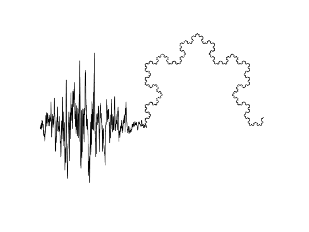

## *Spectral-RnB ( Fig.3 ) *

#### *(J.M. Lina, M-C. Foti, 2024)*

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024

- Spectral Analyses of intracranial EEG recordings

- Two regions: 

- Precuneus : 967 (951) epochs NREM2 (NREM3) 

- Anterior Cingulate : 821 (809) epochs NREM2 (NREM3)

- The following sections display:

- a) the standard Fourier spectral densities 

- b) the results of FOOOF algorithm ('no knees') regarding the Gaussian mixture of the 'periodic component'

- c) The **spectral-RnB** results regarding the spectral exponents distribution (with a mixture of Gaussians approximation)

- d) the **spectral-RnB** rhythmic spectrum

 
addpath('./ressources/')
Prec = load('./data/Precuneus_N2_N3_SPECTRAL.mat');
Antc = load('./data/AntCing_N2_N3_SPECTRAL.mat');
f1 = make_fig1(Prec,Antc);

 
addpath('./ressources/')
Prec = load('./data/Precuneus_FOOOF.mat');
Antc = load('./data/AntCing_FOOOF.mat');
f2 = make_fig2(Prec,Antc);

 
addpath('./ressources/')
Prec = load('./data/Precuneus_figu4.mat','N2','N3');
Antc = load('./data/AntCing_figu4.mat','N2','N3');
Prec.beta_samp = 0.5:0.01:4;
Prec.gN2 = make_mixture(Prec.N2.figu4.betas,2,Prec.beta_samp);
Prec.gN3 = make_mixture(Prec.N3.figu4.betas,2,Prec.beta_samp);
Antc.beta_samp = 0.5:0.01:4;
Antc.gN2 = make_mixture(Antc.N2.figu4.betas,3,Antc.beta_samp);
Antc.gN3 = make_mixture(Antc.N3.figu4.betas,3,Antc.beta_samp);

f3 = make_fig3(Prec,Antc);

 
addpath('./ressources/')
Prec = load('./data/Precuneus_figu4.mat','N2','N3');
Antc = load('./data/AntCing_figu4.mat','N2','N3');
f4 = make_fig4(Prec,Antc);